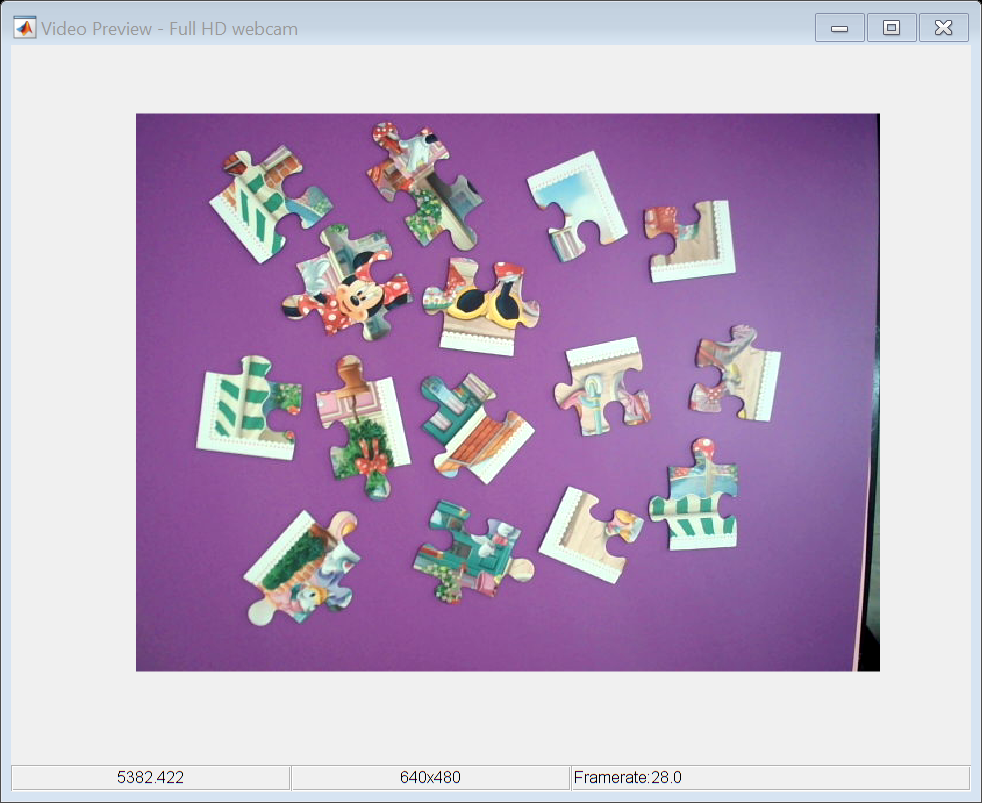

cam = webcam(2);
cam.preview();

% cam.Brightness = 152;
cam.Focus      = 0;
cam.FocusMode  = 'manual';
% cam.Contrast = 35;
cam.Exposure = -5;
cam.Resolution = '640x480';
% cam.Resolution = '640x480';



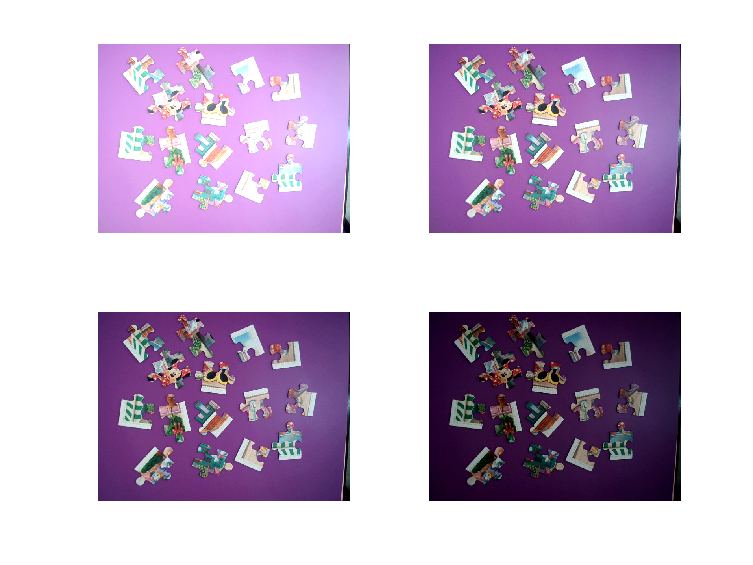

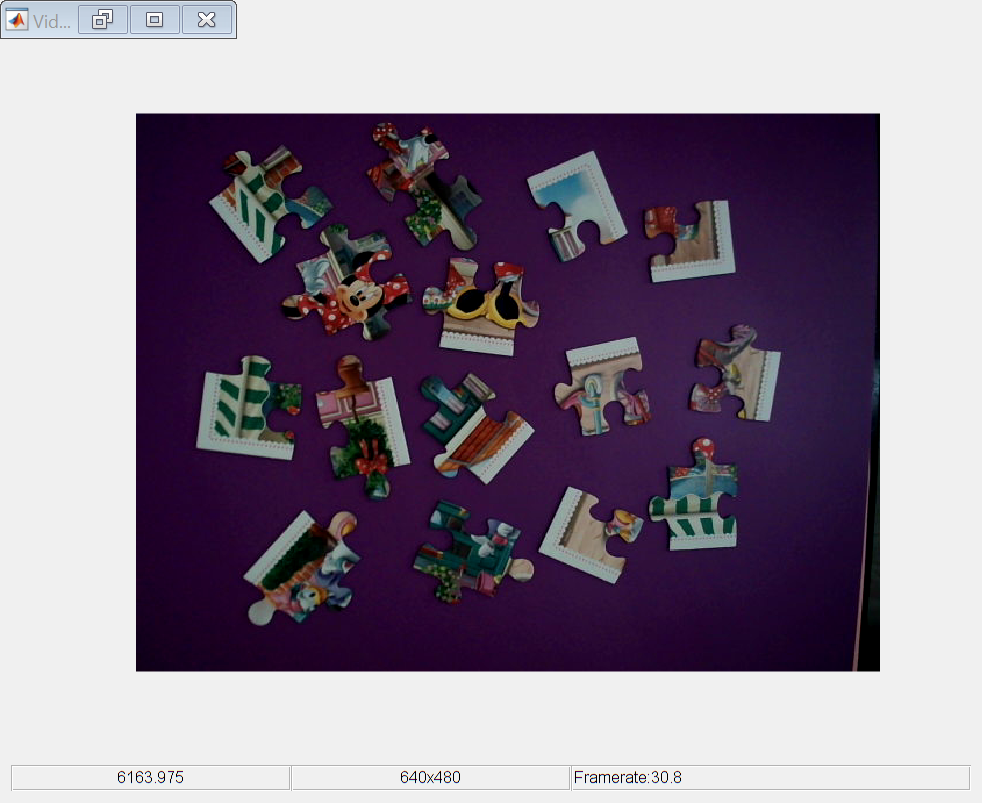

figure;
start_exp = -3;
imgCell = cell(4,1);
cam.Exposure = start_exp-1;

for i=1:4
    subplot(2,2,i);
    cam.Exposure = start_exp-i;
    pause(0.2);
    img = snapshot(cam);
    imgCell{i} = img;
    imshow(img);
end

% exposure = [0.1000 0.3333 0.6250  2.0000];
exposure = [1.8 1.2 0.8 0.3];
relExposure = exposure./exposure(1);

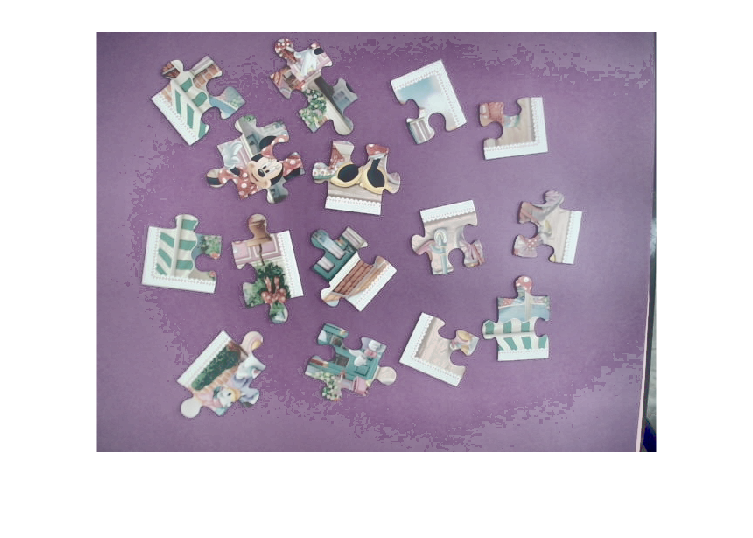

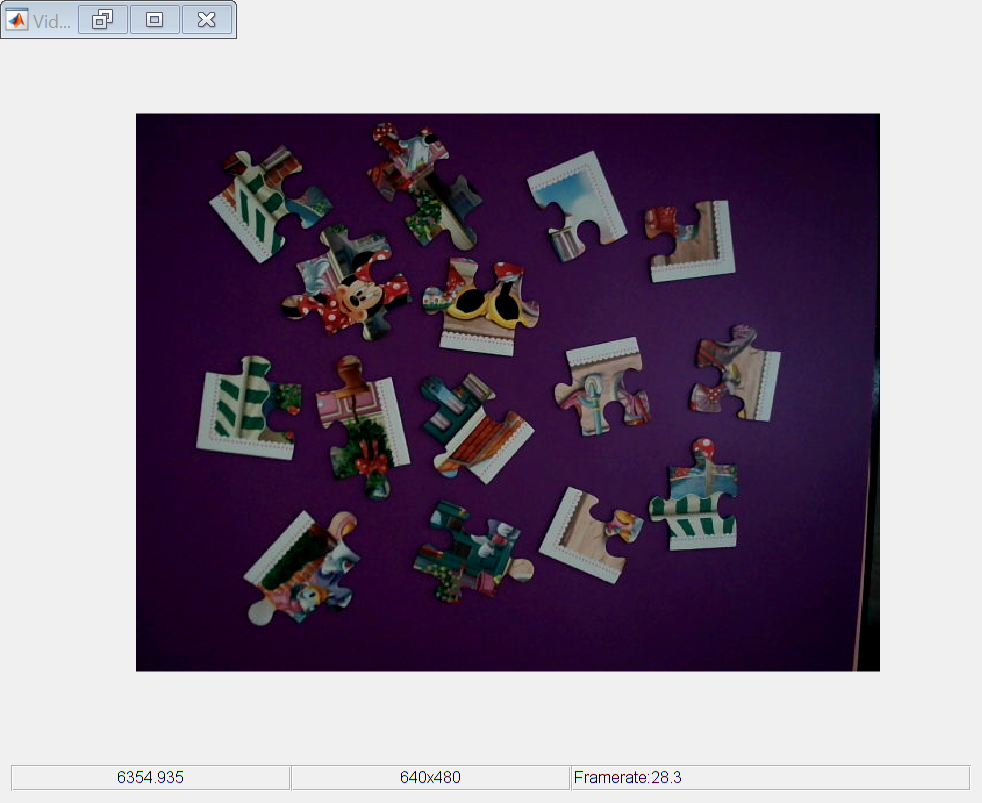

hdr_img = makehdr(imgCell,'RelativeExposure',relExposure);
rgb = tonemap(hdr_img);
figure;
imshow(rgb)